# Contour diagrams

## Introduction

A contour diagram is a graph that allows you to visualise three-dimensional data in a two-dimensional plot. This type of graph is widely used in cartography, where contour lines on a topological map indicate elevations that are the same. Many other disciples use contour diagrams including: astrology, meteorology, and physics. Contour lines commonly show altitude (like height of a geographical features), but they can also be used to show density, brightness, or electric potential.

In this activity we will learn how to use some basic commands to plot contour diagrams in two and three dimensions.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

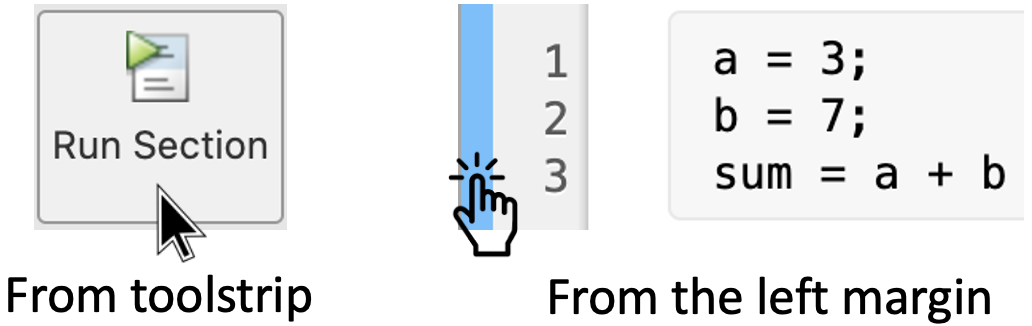

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Contour diagrams in two dimensions

### 1.1 Method 1: Two independent plots

The easiest way to plot a contour diagram in MATLAB is using the command [`contour()`](https://au.mathworks.com/help/matlab/ref/contour.html). First we can define and plot our surface, using the command [`surf()`](https://au.mathworks.com/help/matlab/ref/surf.html).

For example, consider the function $f:[-2,2]\times[-6,6] \to \mathbb R$ defined as

$f(x,y) = 80y^2 \exp\left(-x^2-0.3y^2\right)$.

To plot $f$ and its contour diagram we use the following code:

clf % This command removes previous plots, if there are any
[x, y] = meshgrid(-2:0.15:2, -6:0.15:6);
z = 80 * y.^2.* exp(-x.^2 - 0.3 * y.^2);
surf(x,y,z);
contour(x,y,z,10);
%colorbar;

Run this section to see the result. You should get 1) one plot for the surface and 2) another plot for the contour diagram.

**Note 1:** If you prefer to plot only the contour diagram, just add the symbol `%` in the previous code before the command `surf`. Then re-run this section to see the result.

**Note 2: **The last argument (`10`) in the command `contour()` specifies the number of contour levels. Change that number and re-run the section to see the output.

**Note 3: **If you want to add a colour bar, uncomment the last line in the previous code and re-run this section. For more information about this command see: [`colorbar`](https://au.mathworks.com/help/matlab/ref/colorbar.html).

### 1.2 Method 2: Two plots on the same figure

As you already have noticed in the previous example, MATLAB creates two separate plots, a surface and a contour diagram. It is possible to plot them together on the same figure using the command [`subplot()`](https://au.mathworks.com/help/matlab/ref/subplot.html). 

For example, the code below creates the same plots from section1.1 but on the same figure. Run this section to see the result.

clf
subplot(1,2,1);
[x, y] = meshgrid(-2:0.15:2, -6:0.15:6);
z = 80 * y.^2.* exp(-x.^2 - 0.3 * y.^2);
surf(x,y,z);

subplot(1,2,2);
contour(x,y,z);
colorbar;

**Note 4:** We use the command [`clf`](https://au.mathworks.com/help/matlab/ref/clf.html) (clear figure) at the begining to remove all children (other plots) of the current plots that have [visible handles](https://au.mathworks.com/help/matlab/ref/clf.html#mw_f3d99dc1-0a01-41b8-bd9f-dddf794535a2).

### 1.3 Method 3: Plotting a surface with a contour diagram underneath

Another way to plot contour diagrams is with the command [`surfc()`](https://au.mathworks.com/help/matlab/ref/surfc.html), which allows us to create a three-dimensional surface plot with a contour diagram underneath.

For example, consider the function $f:[1,10]\times[1,20] \to \mathbb R$ defined as

$f(x,y) = \sin x + \cos y$.

Run this section to see the plot of the surface $f$ with a contour diagram underneath.

clf
[X,Y] = meshgrid(1:0.25:10,1:0.25:20);
Z = sin(X) + cos(Y);
surfc(X,Y,Z)

## 2. Contour diagrams in three dimensions

In MATLAB we can also visualise contour diagrams in three dimensions using the command [`contour3()`](https://au.mathworks.com/help/matlab/ref/contour3.html). 

For example, let $f:[-5,5]\times[-5,5] \to \mathbb R$ be a function defined by

$f(x,y) = x^2+y^2$.

To plot its contour diagram in three dimension we use the following code:

clf
[X1,Y1] = meshgrid(-5:0.2:5);
Z1 = X1.^2 + Y1.^2;
contour3(X1, Y1, Z1, 10)
xlabel('x') % Labels x axis
ylabel('y') % Labels y axis

**Note 5:** The last argument (`10`) in the command `contour3()` specifies the number of contour levels. Change that number and re-run the section to see the output.

**Remark:** MATLAB has multiple commands to plot contour diagrams with different features to analyse functions. Here we just covered the most used. To learn more about other similar commands consult: [Contour Plots](https://au.mathworks.com/help/matlab/contour-plots-1.html).

## 3. Hands on practice

#### Activity 1:

Plot the contour diagram in two dimensions for the following functions:

- $f(x) = \sin(xy)$ for $x\in[-3,3]$ and $y\in [-3,3]$

- $g(x) = \frac{x-y}{1+x^2+y^2$ for $x\in[-4,4]$ and $y\in [-4,4]$

- $h(x) = \exp\left(-\left(x^2+y^2\right)/3\right)\left[\sin x^2 + \cos y^2\right]$ for $x\in[-4,4]$ and $y\in [-4,4]$

You can use any of the methods described above.

Write your code here:

% Using Method 1: only contour diagram :)

% Part 1: f(x) = sin(xy)
clf
[x, y] = meshgrid(-3:0.2:3, -3:0.2:3);
z = sin(x.* y);
contour(x,y,z,10);
colorbar;

% Part 2: g(x) = (x-y)/(1+x^2+y^2)
clf
[x, y] = meshgrid(-4:0.15:4, -4:0.15:4);
z = (x-y)./(1+x.^2+y.^2);
contour(x,y,z,20);
colorbar;

% Part 3: h(x) = (x-y)/(1+x^2+y^2)
clf
[x, y] = meshgrid(-4:0.1:4, -4:0.1:4);
z = exp(-(x.^2+y.^2)./3).*(sin(x.^2)+ cos(y.^2));
contour(x,y,z,30);
colorbar;

Compare the contour diagrams. What do you notice? What do you wonder?

#### Activity 2:

**Part 1 - Temperature**

A thin metal plate, located in the $xy$-plane, has temperature $T(x,y)$ at the point $(x,y)$. Plot a contour diagram if the temperature function is given by

$T(x,y)=\frac{100}{1+x^2+2y^2}$.

Write your code here:

clf
[x, y] = meshgrid(-3:0.15:3, -3:0.15:3);
z = 100./(1+x.^2 + 2* y.^2);
contour(x,y,z,20);
colorbar;

#### Part 2 - Electric potential

If $V(x,y)$ is the electric potential at a point $(x,y)$ in the $xy$-plane, then the level curves of $V$ are called *equipotential curves* because at all points on such a curve the electric potential is the same. If we have that

$V(x,y) = \frac{c}{\sqrt{r^2-x^2-y^2}}$, where $c$ is a positive constant.

Choose carefully some values of $c$ and $r$ in order to plot some equipotential curves of this the electric potential (i.e. a contour diagram).

Write your code here:

clf
[x, y] = meshgrid(-3:0.15:3, -3:0.15:3);
% define constants
c = 1.5;
r = 6;
z = c./sqrt(r.^2-x.^2 -y.^2);
contour(x,y,z,20);
colorbar;


Compare both contour diagrams. What do you notice? What do you wonder?